clear all

figure();
%subplot(1,2,1)
%biomass_5000_0=zeros(352,352);
run("biomass_at2400.m")

fp1=figure() 

fp1 =   Figure (3) with properties:

      Number: 3
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [488 342 560 420]
       Units: 'pixels'

  Show all properties


Xgrid=352

Xgrid = 352

Ygrid=352

Ygrid = 352

norm=1000;

%var=full(biomass_2000_0)/norm;
var_0=1.0-full(biomass_2400_0);

%max=max(var_0(:,:))

max=1.0

max = 1


for x=1:Xgrid
    for y=1:Ygrid
        %C(x,y)=1-(var_0(x,y))/max;
        C(x,y)=(var_0(x,y))/max;
    end
end


s=pcolor(1:Xgrid,1:Ygrid,C)

s =   Surface with properties:

       EdgeColor: [0 0 0]
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 76 77 78 79 80 … ]
           YData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 76 77 78 79 80 … ]
           ZData: [352×352 double]
           CData: [352×352 double]

  Show 

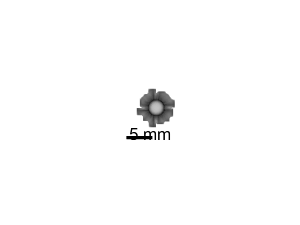

hold on
s.EdgeColor = 'none';
ax=gca;
ax.Box = 'off';
ax.XGrid = 'off';
ax.YGrid = 'off';
ax.ZGrid = 'off';
ax.XTick = [];
ax.YTick = [];
ax.ZTick = [];
ax.ZColor = 'none';
ax.YColor = 'none';
ax.XColor = 'none';
colormap(ax,gray);
axis equal

hold on
x=[120 170];
y=[120 120];
line(x,y,'Color','black','LineWidth',2)
text(125,128,'5 mm','Color','black',"FontSize",10)
%text(110,240,'a','Color','black',"FontSize",20)
xlim([0 352])
ylim([0 352])
hold off

f=gcf

f =   Figure (3) with properties:

      Number: 3
        Name: ''
       Color: [1 1 1]
    Position: [488 342 560 420]
       Units: 'pixels'

  Show all properties


exportgraphics(f,"biomass_at_2400.png",'Resolution', 300)